# Exercises 7.2

3. Solve the boundary value problem using the Galerkin method and two basis function.

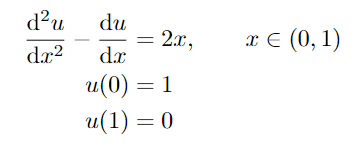

Compare the results with the analytical solution. Explain why the Galerkin method was able to match the analytical result.

clear all
clc
syms x
syms c1

N1 = x*(x-1);
N2 = 1-x;
u  = @(x) c1*N1+N2;
R  = @(x) diff((u(x)),2) - diff((u(x))) - 2*x;
w1 = N1;
A = int(R(x)*w1, 0, 1);
c1 = solve (A, c1);
u  = @(x) c1*N1+N2;
R  = @(x) diff((u(x)),2) - diff((u(x))) - 2*x;
ux = u(x)

$$ux = 1-x$$

Rx = R(x)

$$Rx = 1-2\,x$$

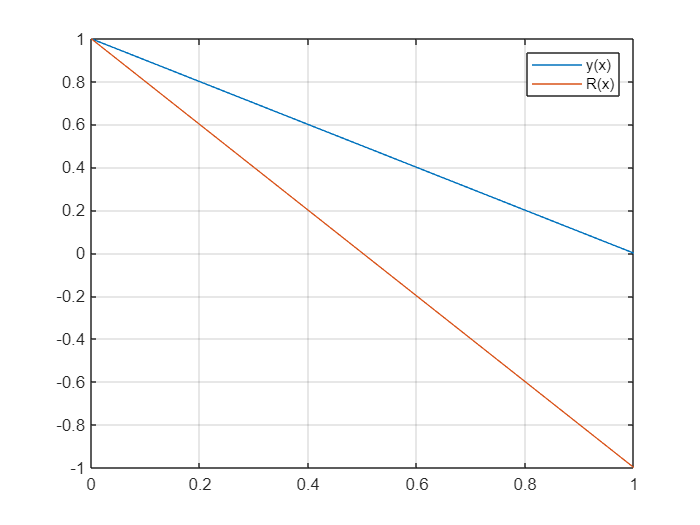

X = 0:0.01:1;
u = subs (ux,x, X);
R = subs (Rx,x, X);
plot(X,u,X,R)
legend ('y(x)','R(x)')
grid on